## The robot is the spiral, just thickened and discretized

So we will visualize:

1. The spiral backbone

2. How parameters change the spiral

3. How width → robot body

4. Why taper appears

5. Why curvature changes

6. How robot units come from spiral

#  Plot a basic logarithmic spiral

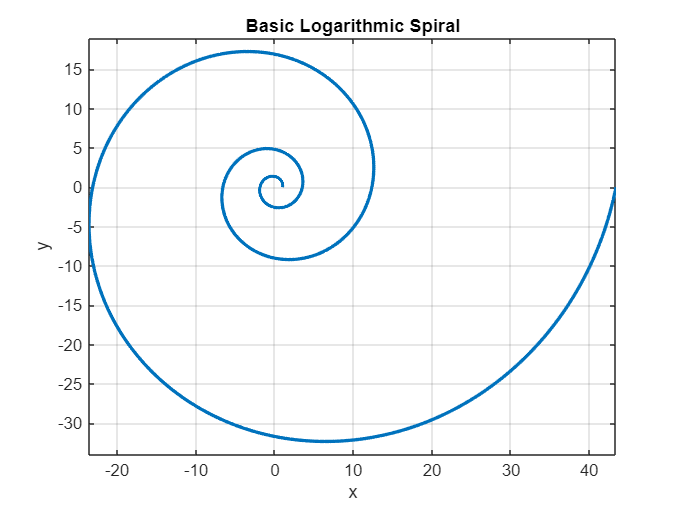

clc; clear; close all;

% Spiral parameters
a = 1;          % size
b = 0.2;        % tightness
theta = linspace(0, 6*pi, 1000);

% Logarithmic spiral
r = a * exp(b * theta);

% Convert to Cartesian
x = r .* cos(theta);
y = r .* sin(theta);

figure;
plot(x, y, 'LineWidth', 2);
axis equal; grid on;
title('Basic Logarithmic Spiral');
xlabel('x'); ylabel('y');

# Effect of parameter **"a"** (size of robot)

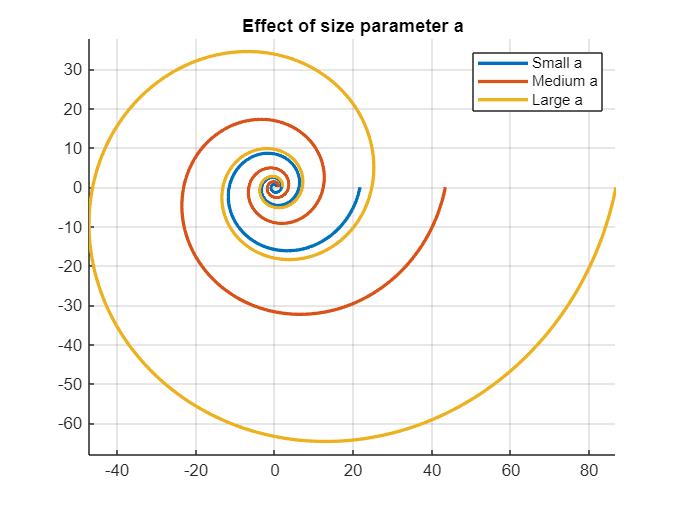

figure; hold on;
a_values = [0.5 1 2];

for a = a_values
    r = a * exp(b * theta);
    plot(r .* cos(theta), r .* sin(theta), 'LineWidth', 2);
end

axis equal; grid on;
legend('Small a','Medium a','Large a');
title('Effect of size parameter a');

# Effect of pḁrameter ****b**** (tightness / curl)

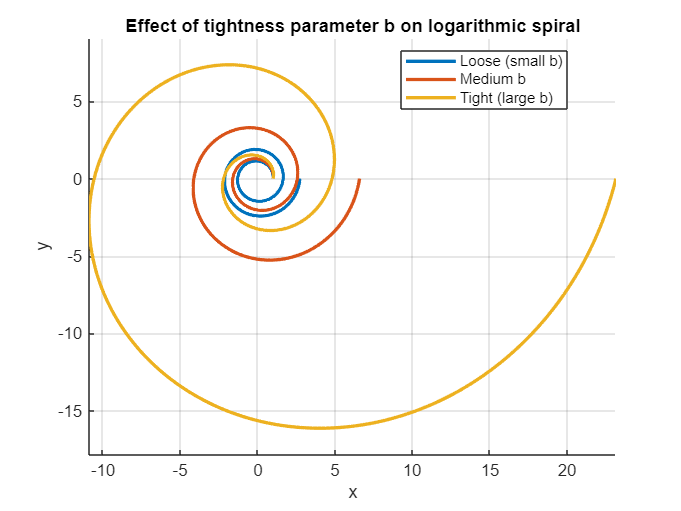

clc; clear; close all;

% Angle range (LIMITED to avoid exponential explosion)
theta = linspace(0, 4*pi, 800);

% Tightness values (small, medium, large)
b_values = [0.08, 0.15, 0.25];
labels = {'Loose (small b)', 'Medium b', 'Tight (large b)'};

figure; hold on;

for i = 1:length(b_values)
    b = b_values(i);

    % Logarithmic spiral
    r = exp(b * theta);

    % Convert to Cartesian
    x = r .* cos(theta);
    y = r .* sin(theta);

    plot(x, y, 'LineWidth', 2);
end

axis equal;
grid on;
xlabel('x');
ylabel('y');
title('Effect of tightness parameter b on logarithmic spiral');
legend(labels, 'Location', 'best');

# Inner and outer spiral → robo̥t width

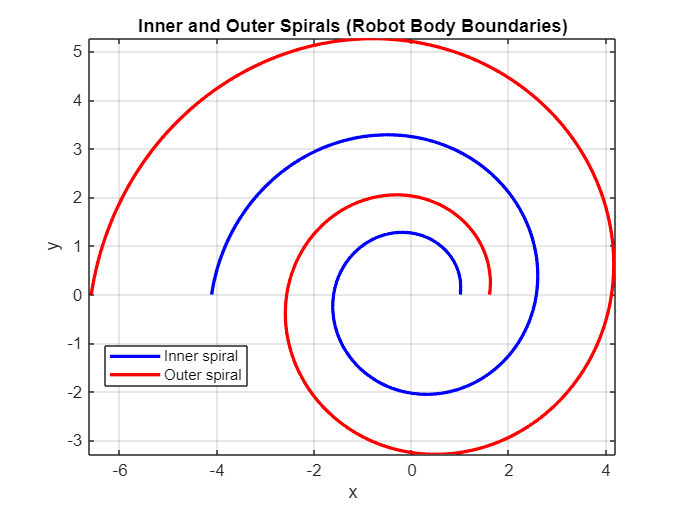

clc; clear; close all;

% -------------------------
% PARAMETERS (SAFE VALUES)
% -------------------------
a = 1;              % scale
b = 0.15;           % tightness (realistic)
theta = linspace(0, 3*pi, 800);  % LIMITED range

% -------------------------
% INNER & OUTER SPIRALS
% -------------------------
r_inner = a * exp(b * theta);
r_outer = a * exp(b * (theta + pi));   % <<< KEY FIX (NOT 2*pi)

% Convert to Cartesian
x_in = r_inner .* cos(theta);
y_in = r_inner .* sin(theta);

x_out = r_outer .* cos(theta);
y_out = r_outer .* sin(theta);

% -------------------------
% PLOT
% -------------------------
figure;
plot(x_in, y_in, 'b', 'LineWidth', 2); hold on;
plot(x_out, y_out, 'r', 'LineWidth', 2);

axis equal;
grid on;
xlabel('x');
ylabel('y');
title('Inner and Outer Spirals (Robot Body Boundaries)');
legend('Inner spiral','Outer spiral','Location','best');

# ̥Central spiral (robot spine)

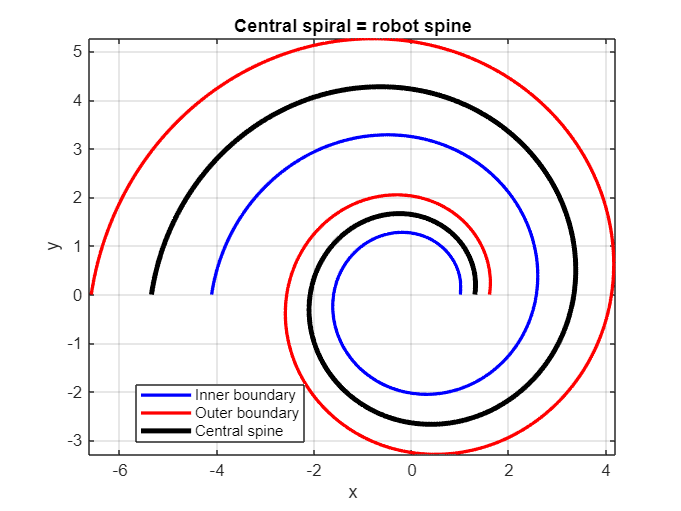

clc; clear; close all;

% -------------------------
% PARAMETERS (CONSISTENT)
% -------------------------
a = 1;                  % scale
b = 0.15;               % tightness
theta = linspace(0, 3*pi, 800);   % limited range

% -------------------------
% INNER & OUTER SPIRALS
% -------------------------
r_inner = a * exp(b * theta);
r_outer = a * exp(b * (theta + pi));   % safe offset

x_inner = r_inner .* cos(theta);
y_inner = r_inner .* sin(theta);

x_outer = r_outer .* cos(theta);
y_outer = r_outer .* sin(theta);

% -------------------------
% CENTRAL (SPINE) SPIRAL
% -------------------------
rc = (r_inner + r_outer) / 2;
x_center = rc .* cos(theta);
y_center = rc .* sin(theta);

% -------------------------
% PLOT
% -------------------------
figure;
plot(x_inner, y_inner, 'b', 'LineWidth', 2); hold on;
plot(x_outer, y_outer, 'r', 'LineWidth', 2);
plot(x_center, y_center, 'k', 'LineWidth', 3);

axis equal;
grid on;
xlabel('x');
ylabel('y');
legend('Inner boundary','Outer boundary','Central spine','Location','best');
title('Central spiral = robot spine');

# Why taper ̥happens automatically

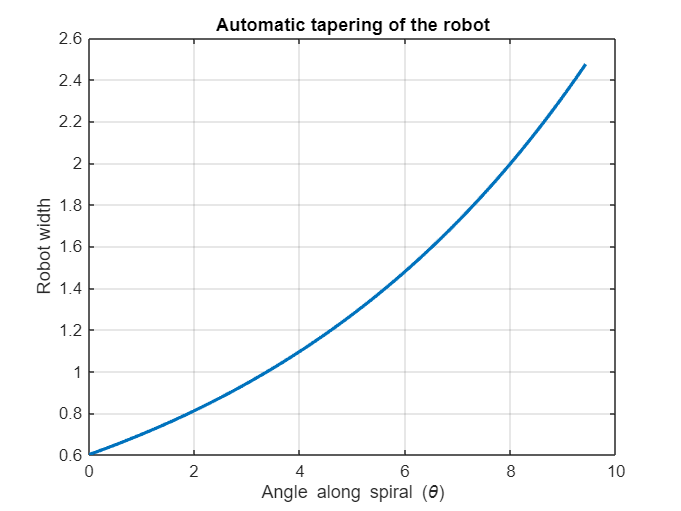

clc; clear; close all;

% -------------------------
% PARAMETERS
% -------------------------
a = 1;                  % scale
b = 0.15;               % tightness
theta = linspace(0, 3*pi, 800);   % safe angular range

% -------------------------
% SPIRALS
% -------------------------
r_inner = a * exp(b * theta);
r_outer = a * exp(b * (theta + pi));   % safe offset

rc = (r_inner + r_outer) / 2;
width = r_outer - r_inner;

figure;
plot(theta, width, 'LineWidth', 2);
grid on;
xlabel('Angle along spiral (\theta)');
ylabel('Robot width');
title('Automatic tapering of the robot');

# Discretization → robot units

Robot is made by cutting at fixed angle steps.

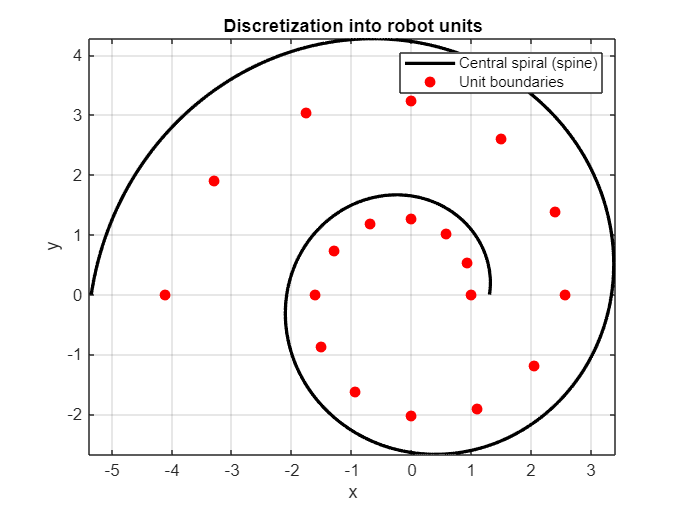

Delta_theta = pi/6;      % 30 degrees (same as paper)
theta_d = 0:Delta_theta:3*pi;

r_d = a * exp(b * theta_d);

x_spiral = rc .* cos(theta);
y_spiral = rc .* sin(theta);

x_d = r_d .* cos(theta_d);
y_d = r_d .* sin(theta_d);

figure;
plot(x_spiral, y_spiral, 'k', 'LineWidth', 2); hold on;
plot(x_d, y_d, 'ro', 'MarkerFaceColor', 'r');

axis equal;
grid on;
xlabel('x');
ylabel('y');
title('Discretization into robot units');
legend('Central spiral (spine)', 'Unit boundaries');

# C̥urvature along the robot (why tip bends more)

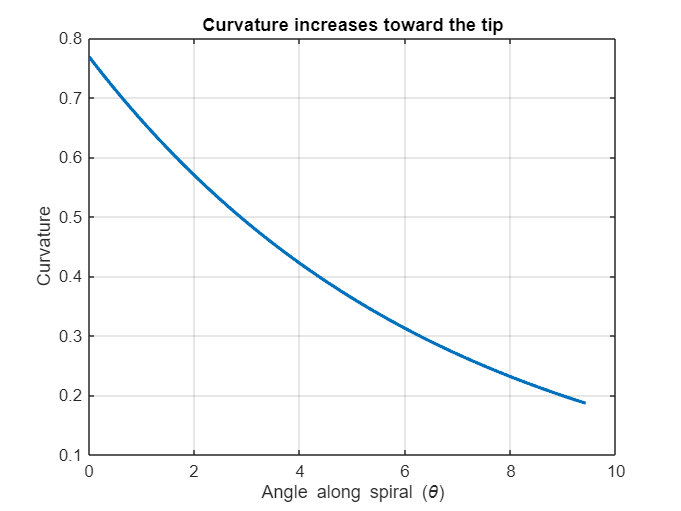

curvature = 1 ./ rc;   % curvature ∝ 1 / radius

figure;
plot(theta, curvature, 'LineWidth', 2);
grid on;
xlabel('Angle along spiral (\theta)');
ylabel('Curvature');
title('Curvature increases toward the tip');

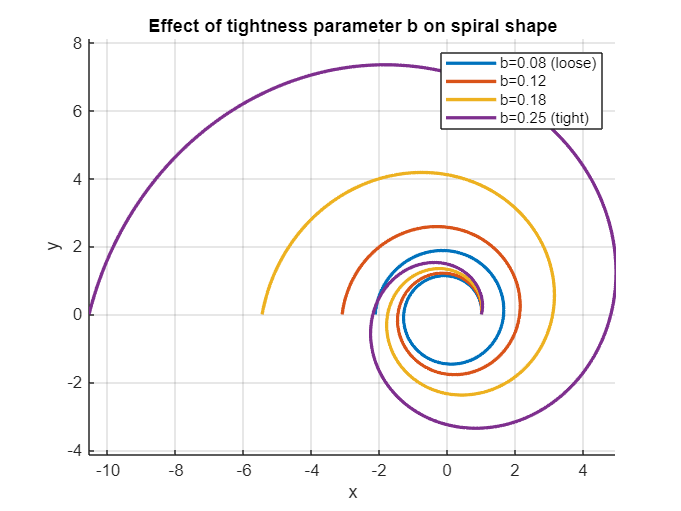

%% SpiRob Design Visualization and Parameter Selection
% This script helps visualize how logarithmic spiral parameters
% affect the shape, taper, curvature, and discretization of a
% 2-cable SpiRob robot.

clc; clear; close all;

%% -------------------------
% BASIC PARAMETERS
% -------------------------
theta = linspace(0, 3*pi, 800);   % limited angle range (avoids explosion)
Delta_theta = pi/6;               % discretization (30 degrees)
a = 1;                            % scale parameter (size)
b_values = [0.08 0.12 0.18 0.25]; % candidate tightness values

%% ===============================================================
%% 1. EFFECT OF b ON SPIRAL SHAPE (REACH VS CURL)
% b controls how fast the spiral curls.
% Small b -> long reach, weak grip
% Large b -> short reach, strong grip

figure; hold on;
for b = b_values
    r = a * exp(b * theta);
    plot(r .* cos(theta), r .* sin(theta), 'LineWidth', 2);
end
axis equal; grid on;
xlabel('x'); ylabel('y');
title('Effect of tightness parameter b on spiral shape');
legend('b=0.08 (loose)','b=0.12','b=0.18','b=0.25 (tight)');

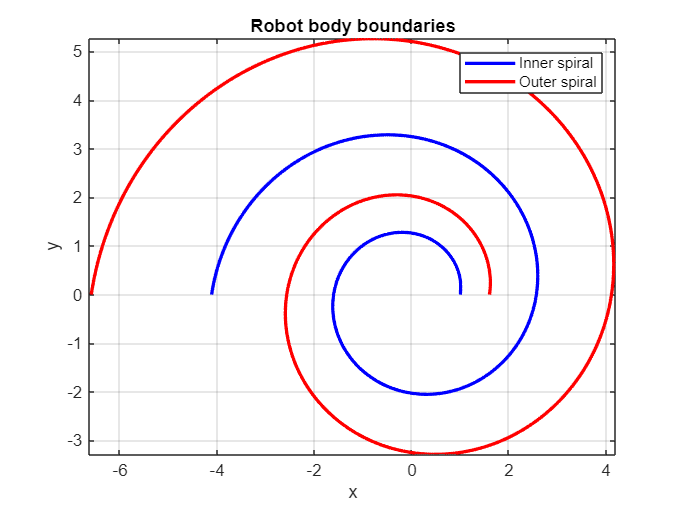


%% ===============================================================
%% 2. ROBOT BODY BOUNDARIES (INNER & OUTER SPIRALS)
% Robot body is the region between two spirals.
% Outer spiral is offset by pi (safe visualization choice).

b = 0.15;   % choose a medium b for demonstration

r_inner = a * exp(b * theta);
r_outer = a * exp(b * (theta + pi));  % outer boundary

x_inner = r_inner .* cos(theta);
y_inner = r_inner .* sin(theta);

x_outer = r_outer .* cos(theta);
y_outer = r_outer .* sin(theta);

figure;
plot(x_inner, y_inner, 'b', 'LineWidth', 2); hold on;
plot(x_outer, y_outer, 'r', 'LineWidth', 2);
axis equal; grid on;
xlabel('x'); ylabel('y');
title('Robot body boundaries');
legend('Inner spiral','Outer spiral');

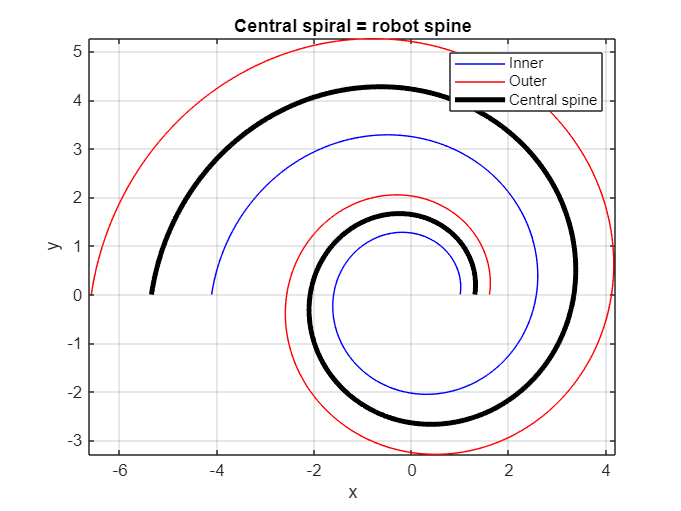


%% ===============================================================
%% 3. CENTRAL SPIRAL (ROBOT SPINE)
% The central spiral is the mechanical backbone of the robot.
% Cables and elastic axis act around this curve.

rc = (r_inner + r_outer) / 2;
x_center = rc .* cos(theta);
y_center = rc .* sin(theta);

figure;
plot(x_inner, y_inner, 'b'); hold on;
plot(x_outer, y_outer, 'r');
plot(x_center, y_center, 'k', 'LineWidth', 3);
axis equal; grid on;
xlabel('x'); ylabel('y');
title('Central spiral = robot spine');
legend('Inner','Outer','Central spine');

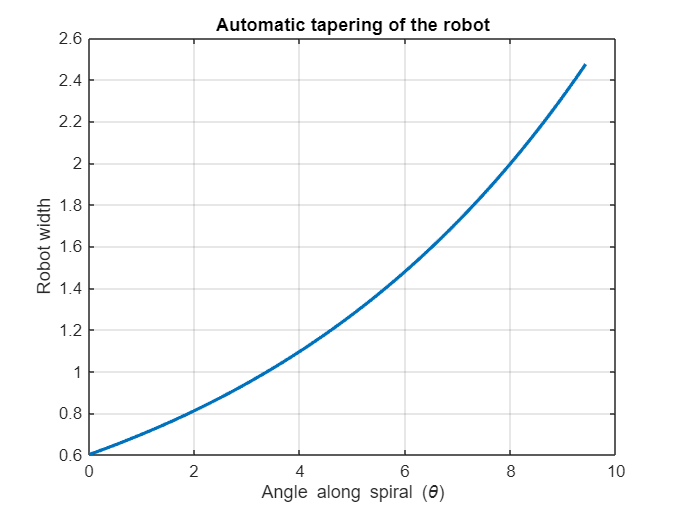


%% ===============================================================
%% 4. AUTOMATIC TAPERING (WIDTH GROWTH)
% Robot width increases naturally due to spiral geometry.
% This explains taper angle without explicitly designing it.

width = r_outer - r_inner;

figure;
plot(theta, width, 'LineWidth', 2);
grid on;
xlabel('Angle along spiral (\theta)');
ylabel('Robot width');
title('Automatic tapering of the robot');

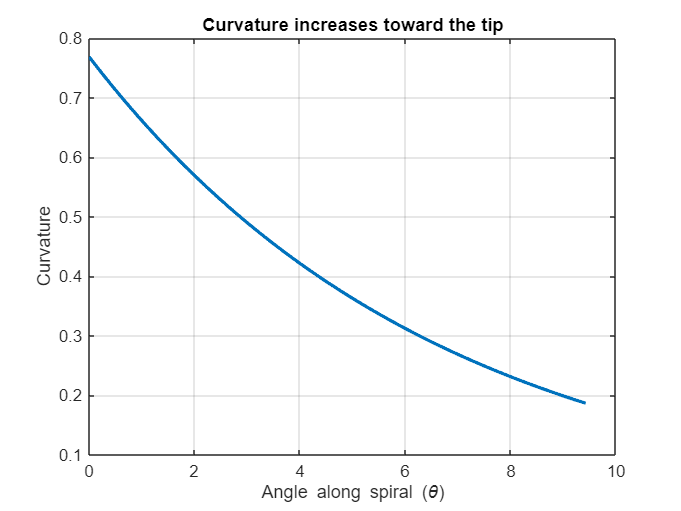


%% ===============================================================
%% 5. CURVATURE ALONG THE ROBOT
% Curvature is inversely proportional to radius.
% Tip has high curvature (flexible)
% Base has low curvature (stiff)

curvature = 1 ./ rc;

figure;
plot(theta, curvature, 'LineWidth', 2);
grid on;
xlabel('Angle along spiral (\theta)');
ylabel('Curvature');
title('Curvature increases toward the tip');

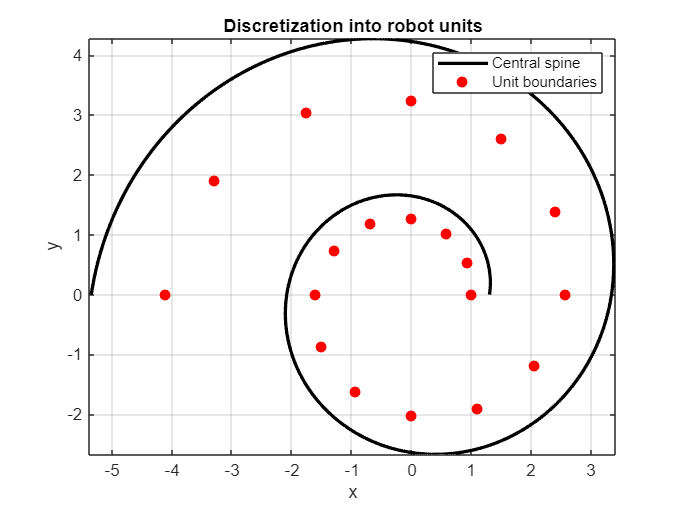


%% ===============================================================
%% 6. DISCRETIZATION INTO ROBOT UNITS
% Robot is fabricated by cutting at fixed angle intervals.
% Each segment is a scaled copy of the previous one.

theta_d = 0:Delta_theta:3*pi;
r_d = a * exp(b * theta_d);

x_d = r_d .* cos(theta_d);
y_d = r_d .* sin(theta_d);

figure;
plot(x_center, y_center, 'k', 'LineWidth', 2); hold on;
plot(x_d, y_d, 'ro', 'MarkerFaceColor', 'r');
axis equal; grid on;
xlabel('x'); ylabel('y');
title('Discretization into robot units');
legend('Central spine','Unit boundaries');

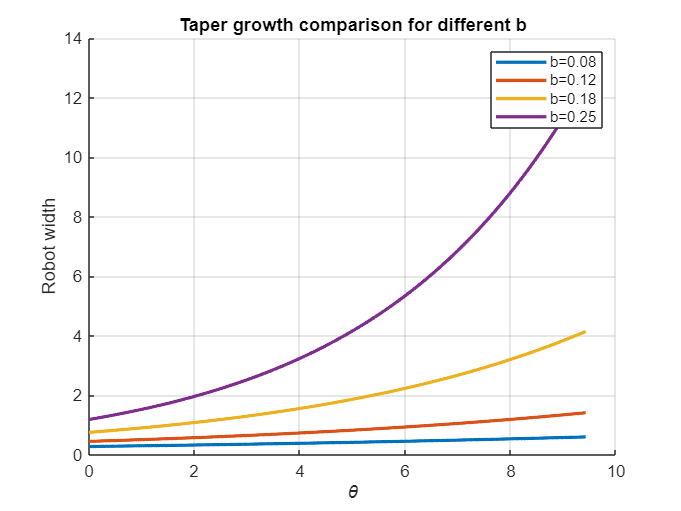


%% ===============================================================
%% 7. COMPARING TAPER FOR DIFFERENT b VALUES
% Helps choose best b for a 2-cable SpiRob

figure; hold on;
for b = b_values
    r_i = exp(b * theta);
    r_o = exp(b * (theta + pi));
    plot(theta, r_o - r_i, 'LineWidth', 2);
end
grid on;
xlabel('\theta');
ylabel('Robot width');
title('Taper growth comparison for different b');
legend('b=0.08','b=0.12','b=0.18','b=0.25');

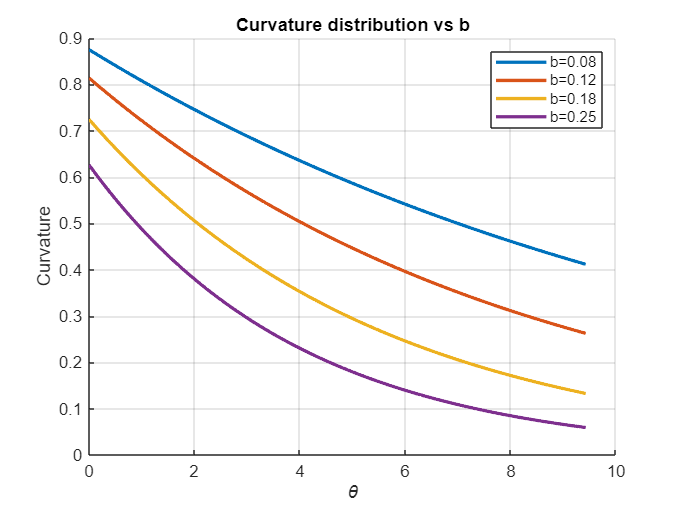


%% ===============================================================
%% 8. COMPARING CURVATURE FOR DIFFERENT b VALUES
% Shows how stiffness distribution changes with b

figure; hold on;
for b = b_values
    r_i = exp(b * theta);
    r_o = exp(b * (theta + pi));
    rc_temp = (r_i + r_o) / 2;
    plot(theta, 1 ./ rc_temp, 'LineWidth', 2);
end
grid on;
xlabel('\theta');
ylabel('Curvature');
title('Curvature distribution vs b');
legend('b=0.08','b=0.12','b=0.18','b=0.25');

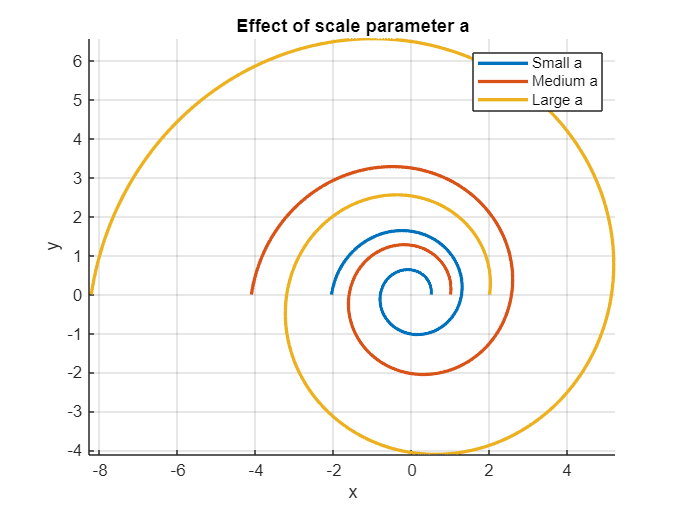


%% ===============================================================
%% 9. EFFECT OF a (SIZE SCALING ONLY)
% a scales the robot without changing its behavior.

b = 0.15;
a_values = [0.5 1 2];

figure; hold on;
for a = a_values
    r = a * exp(b * theta);
    plot(r .* cos(theta), r .* sin(theta), 'LineWidth', 2);
end
axis equal; grid on;
xlabel('x'); ylabel('y');
title('Effect of scale parameter a');
legend('Small a','Medium a','Large a');


%% ===============================================================
%% FINAL DESIGN GUIDANCE (READ THIS)
% For a 2-cable SpiRob:
% - Choose b first (controls behavior)
%   Recommended: b ≈ 0.12 – 0.18
% - Then choose a based on desired length and printer limits
% - Use Delta_theta = 30° for fabrication
%
% Geometry gives:
% - Automatic taper
% - Flexible tip + stiff base
% - Smooth planar grasping

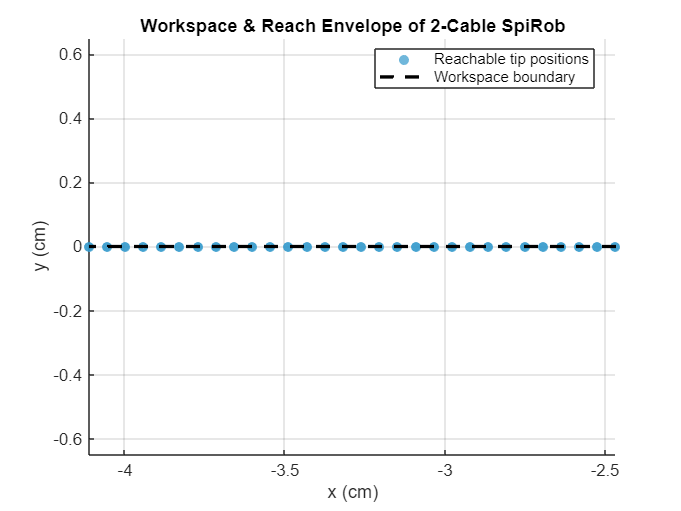

%% Workspace & Reach Envelope (Paper-Style Visualization)
% This section reproduces a workspace plot similar to the SpiRobs paper:
% - x–y reach envelope of the robot tip
% - multiple static configurations
% - planar (2-cable) assumption
% - no animation, no fake dynamics
%
% This figure is suitable for:
% - reports
% - presentations
% - design justification

clc; clear; close all;

%% ------------------------------------------------
%% 1. ROBOT & DESIGN PARAMETERS
% ------------------------------------------------
a = 1;                     % scale (size)
b = 0.15;                  % chosen tightness (balanced for 2-cable)
theta_max = 3*pi;          % robot length (angular domain)
theta = linspace(0, theta_max, 600);

% Quasi-static curl levels (packing → reaching)
curl_levels = linspace(0.6, 1.0, 30);   % 0.6 = packed, 1.0 = extended

%% ------------------------------------------------
%% 2. COLLECT TIP POSITIONS (WORKSPACE SAMPLING)
% ------------------------------------------------
tip_positions = [];

% Nominal spiral geometry
r0 = a * exp(b * theta);

for c = curl_levels

    % Scale curvature (static assumption)
    r = r0 * c;

    % Tip location
    x_tip = r(end) * cos(theta(end));
    y_tip = r(end) * sin(theta(end));

    % 2-cable planar symmetry (left / right)
    tip_positions = [tip_positions;
                     x_tip,  y_tip;
                     x_tip, -y_tip];
end

%% ------------------------------------------------
%% 3. COMPUTE REACH ENVELOPE (BOUNDARY)
% ------------------------------------------------
% Convex hull approximates the reachable workspace boundary
k = convhull(tip_positions(:,1), tip_positions(:,2));
x_env = tip_positions(k,1);
y_env = tip_positions(k,2);

%% ------------------------------------------------
%% 4. PLOT WORKSPACE (PAPER-STYLE)
% ------------------------------------------------
figure;
hold on;

% Workspace points
scatter(tip_positions(:,1), tip_positions(:,2), ...
        35, [0.2 0.6 0.8], 'filled', 'MarkerFaceAlpha', 0.7);

% Reach envelope
plot(x_env, y_env, 'k--', 'LineWidth', 2);

axis equal;
grid on;
xlabel('x (cm)');
ylabel('y (cm)');
title('Workspace & Reach Envelope of 2-Cable SpiRob');

legend('Reachable tip positions', 'Workspace boundary', ...
       'Location', 'best');


%% ------------------------------------------------
%% 5. INTERPRETATION (FOR REPORT)
% ------------------------------------------------
% - Each dot represents a reachable static tip position
% - Dashed curve is the reach envelope
% - Workspace is planar due to 2-cable actuation
% - Density indicates grasping flexibility
%
% This plot directly corresponds to the workspace
% analysis shown in the SpiRobs paper (planar case).
